**FINAL PROJECT.**

%%%%%%%%%%%%%%%%%%%%%%% Initial Data managment %%%%%%%%%%%%%%%%%%%%

%this part of the code gives access to tif video. 
reader = bfGetReader('pos_1B_20211206S1_spHEK_Mag_60s_90s_5%_5fps_27oC_fiji.tif');

log4j:WARN No appenders could be found for logger (loci.formats.ClassList).
log4j:WARN Please initialize the log4j system properly.



% get the size of the video
Fields=reader.getSizeT

Fields = 1

Channel=reader.getSizeC

Channel = 1

% get the length of the video
Time=reader.getSizeZ

Time = 700

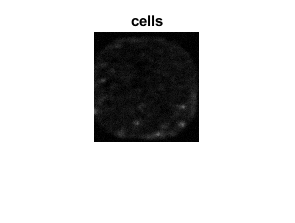

%getting acces to the first frame of the video
chan = 1; z = 1; time = 1;
ind = reader.getIndex(z - 1, chan - 1, time - 1) + 1;
img1_change = bfGetPlane(reader,ind);
img1_original = bfGetPlane(reader,ind);

%selecting the first well of illustrated in the frame 
img1_original=img1_original(1:110,1:105);

%imaging this first well 
figure()
imshow(img1_original,[0 1000])
title('cells')



%%%%%%%%%%%% Identify single of cells %%%%%%%%%%%%

%for this we will process the previous image to segementate it and identify
%single cells. 

%change the image to black and white. 
img1_change = img1_change(1:110,1:105);
img1_change = im2bw(img1_change,0.0016);

% we created the function 'segmentame_esta' 
% which will segmentate groups of cells to single cells. 
img1_change = segmentame_esta(img1_change);
img1_change = bwpropfilt(img1_change,'Area',[1 10])

img1_change = 110×105 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

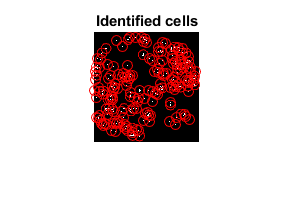


%then we used region props to identify the centroids in the 
img1_centroids= regionprops(img1_change,'centroid');
img1_area= regionprops(img1_change,'area');
fig=can_I_see_the_centroids(img1_centroids,img1_change);


centroids_set=[];
original_intensity1=[];

%%%%%%%%%%%%% detect the fluoresence change on the centroids %%%%%%%%%%%%

% This for loop will scan the change of intesnsity on the centroids
% initially dectected.

for i=1:length(img1_centroids) 
centroids_set(i,:) = round(struct2array(img1_centroids(i)));
check = centroids_set(i,:);
original_intensity1(i,:) = img1_original(check(1),check(2));
end

centroids_set

centroids_set =      3    36
     2    40
     1    59
     3    44
     2    48
     3    66
     3    86
     4    27
     5    56
     5    87


original_intensity1

original_intensity1 =      0
    24
    13
    21
     2
    14
    26
    30
    40
     3



% original_intensity contains the intensity of a centroid over the 700 time
% points 

original_intensity=centroids_overtime(img1_centroids,reader)

original_intensity =      0     0     0     7     1     0    40    45     0     0     0    11    37     0    11     0     0    14    42     0    29     0    41     0     6     0     0     0     0     0     0    22    61     0     0     0    23     0     0     0     7    11     0    31    11     0    17     0     0     0
    24    25    14    23    15     9    13     5    22    43    19    13    24     5    14    19    31    14     1    12    21    18     9    14    22    38    11    14     2    24     9    12     9    12    17    25    35    23    15    22    34    26     0     9    10    18    39     2    29    23
    13    19     0    44    53    16    16    11     5     0    32     6    26    37    24    30     0    15    29    31    31    23    14     7    11    32     2    36     0     5    24     0    28    27     2     0    18     6    44     3    49     7    11    13    12    29    32    12    37    25
    21    26    10    29     2    11     0    27    26     6     0     0    

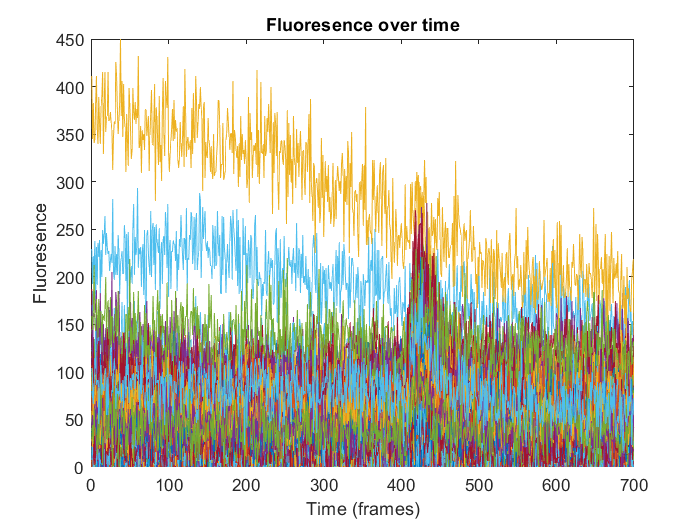


%identifyinf the maximum intensity over the time 
maximum = max(original_intensity,[],2);

% Average of intesity over the time 
New_original_intensity=original_intensity*100./maximum;

%ploting all the singnals found 
figure()
plot(1:700,original_intensity)
title('Fluoresence over time')
xlabel('Time (frames)')
ylabel('Fluoresence')

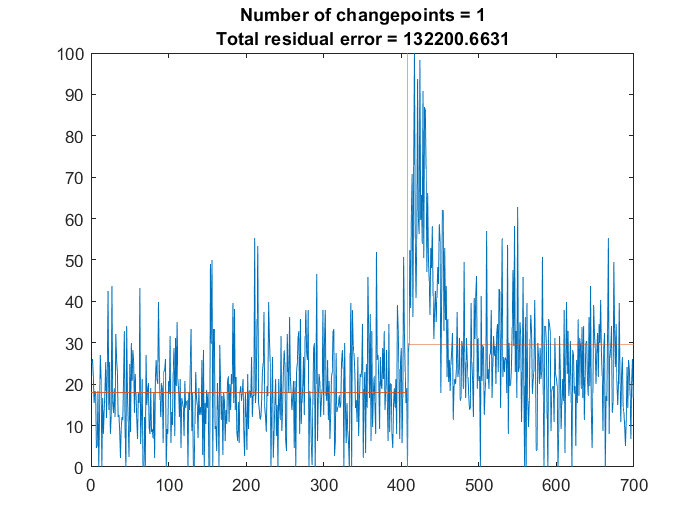


%Detecting drastic changes on the fluoresence. (try)
findchangepts(New_original_intensity(25,:))

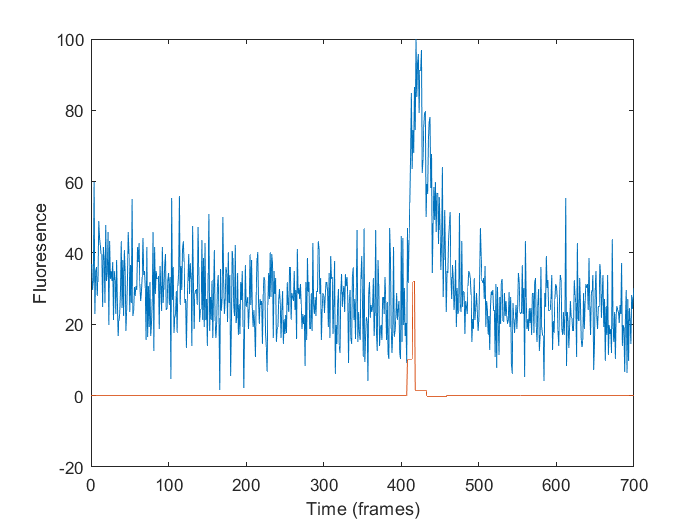


%Detecting drastic changes on the fluoresence. (Selected)
[~,S1,~] = ischange(New_original_intensity(25,:),'linear','Threshold',1300);

figure()
plot(New_original_intensity(12,:))
hold on
plot(S1)
xlabel('Time (frames)')
ylabel('Fluoresence')
hold off 

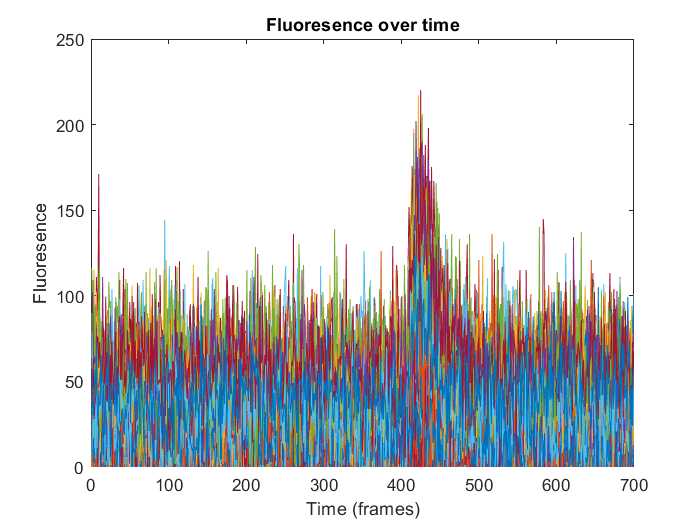

% Maximun values of each cell over the time. 
maximum = max(original_intensity,[],2);

% Mean intesnity over the first 200 timepoints.
mean_total=  mean(original_intensity(:,1:200),2);

% Percentage of original intensity.
new_original_intensity=original_intensity*100./maximum;


% Selecting just data with a significant change of intensity. 
total_data=[];
for i=1:length(mean_total)
    [~,S1,~] = ischange(New_original_intensity(i,:),'linear','Threshold',450);   
    if max(S1)+10 > mean((S1(1,1:100)+10)*5) && mean(New_original_intensity(i,1:100))*3 < max(New_original_intensity(i,:))
       total_data=[total_data;original_intensity(i,:)]; 
    end 
end

total_data;
new_original_intensity=original_intensity*100./maximum;

%refined  data plotted. some of them present a drastic change around the time point 400.   
figure()
plot(1:700,total_data)
title('Fluoresence over time')
xlabel('Time (frames)')
ylabel('Fluoresence')

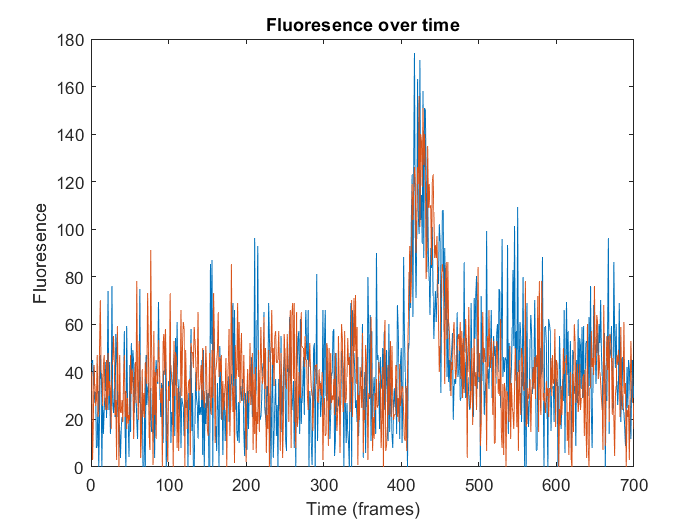



%there is some data that doesnt show a drastic change. 
figure()
plot(1:700,total_data(19:20,:))
title('Fluoresence over time')
xlabel('Time (frames)')
ylabel('Fluoresence')


%space to discuss a better aproach to detect changes but the algorithm
%currently is not working which would be a good one? 


A=length(original_intensity(:,1))

A = 174

B=length(total_data(:,1))

B = 57


percentageof_Wrong_data_eliminated = (A - B)*100/A

percentageof_Wrong_data_eliminated = 67.2414

# **FUNCTIONS** 

function original_intensity=centroids_overtime(img1_centroids,reader)
    
centroids_set=[];
original_intensity=[];

for ii = 1:700
    
    chan = 1; z = 1; 
    time=1;
    ind = reader.getIndex(ii - 1, chan - 1, time - 1) + 1;
    img1_original = bfGetPlane(reader,ind);
    img1_original=img1_original(1:110,1:105);
    

    for i=1:length(img1_centroids) 
   
        centroids_set(i,:) = round(struct2array(img1_centroids(i)));
        check = centroids_set(i,:);
        original_intensity(i,ii) = img1_original(check(1),check(2));

    end

    
end

end 

function fig=can_I_see_the_centroids(stat1B,I1)
%plot centroids
fig=0;
figure();
imshow(I1); hold on; title('Identified cells')
for x = 1: numel(stat1B)
    plot(stat1B(x).Centroid(1),stat1B(x).Centroid(2),'ro');
end

end

function [I1,I2,I3]=gimme_the_images(I,levelr,levelg,levelb)

rmat=I(:,:,1);
gmat=I(:,:,2);
bmat=I(:,:,3);

I1 = im2bw(rmat,levelr);
I2 = im2bw(gmat,levelg);
I3 = im2bw(bmat,levelb);

end 

function segmented_image = segmentame_esta(BW2)
    D = 255-uint8(bwdist(~BW2));
    gs=watershed(D);
    ws=gs==0;
    segmented_image = BW2 & ~ws;
end 
